% Auto-detect everything, plot by default:
out1 = import_clarius_csv("C:\Users\Admin\Documents\FET-Analyzer\B1500_data_export\# Transfer Curve [CHIP012_O7(3) ; 10_7_2025 9_56_45 PM].csv");

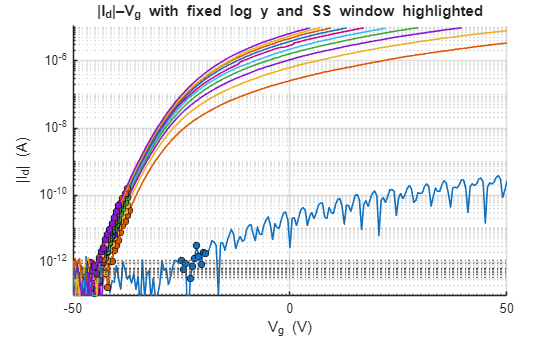

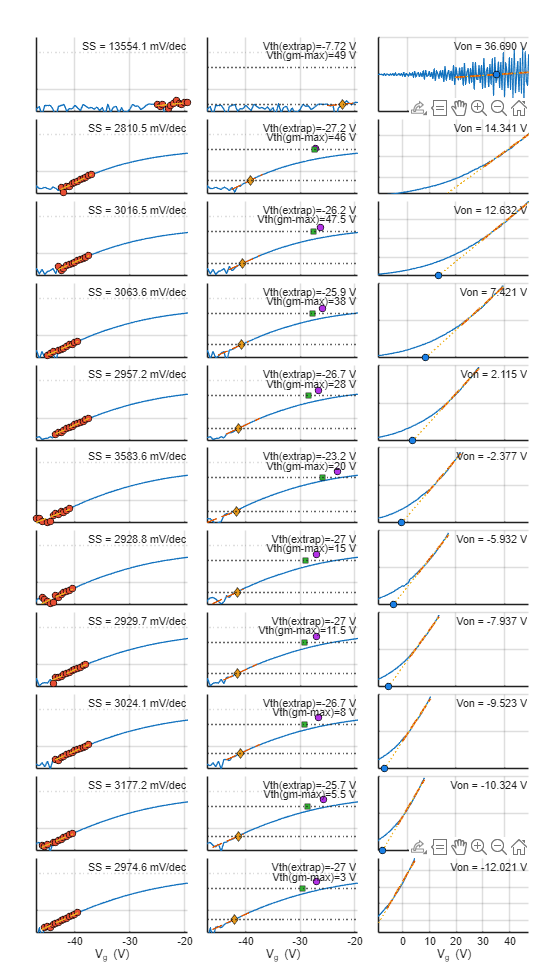

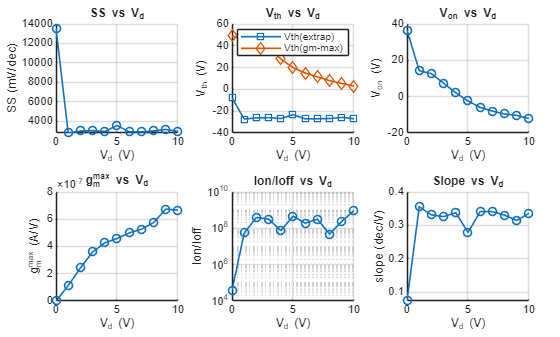

res = analyze_transfer_curves(out1, ...
    "YLim", [1e-13, 1e-3], ...
    "DoPlot", true, ...
    "SmoothingPts", 5, ...
    "PeakFrac", 0.8, ...
    "IoffFrac", 3, ...
    "PadVg", 0.1, ...
    "MinWinPts", 12, ...
    "ComplianceFrac", 0.98, ... 
    "DenoiseWindow", 5, ...   
    "IrefFixed", 1e-7, ...  
    "MinVonPoints", 6, ... 
    "MinVonR2", 0.97, ... 
    "MinVonSlope", 1e-12, ...         
    "MinVonDeltaVg", 0.02 ...          
);

res.Summary

ans = 11×14 table
    Vd    SS_mV_per_dec    Vg_left    Vg_right    Ioff_est     slope_dec_per_V    Ion_Ioff_ratio      gm_max        Vth      Vth_extrap_Ioff    Vth_extrap_Iref    Vth_extrap_cross    Vth_gmmax      Von  
    __    _____________    _______    ________    _________    _______________    ______________    __________    _______    _______________    _______________    ________________    _________    _______

     0        13554           -25      -19.5        1.1e-13       0.073778               38199   

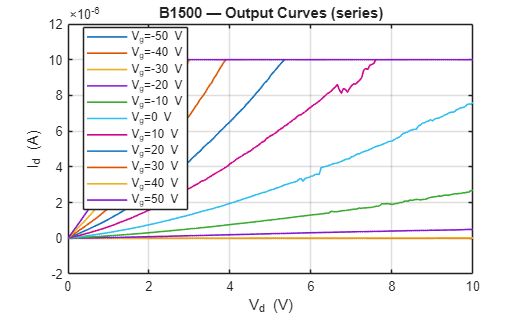

% Force output-curve series, plot on:
out2 = import_clarius_csv("C:\Users\Admin\Documents\FET-Analyzer\B1500_data_export\# Output Curve [CHIP012_O7(3) ; 10_7_2025 9_53_40 PM].csv", ...
                    FileType="output_series", Plot=true);

% 2) 进行输出曲线分析（多曲线或单曲线均可）
res = analyze_output_curves(out2, ...
    "VdLinMax", 0.1, ...        % 线性区上限（|Vd|<=0.1 V）
    "VdSatFrac", 0.6, ...        % 饱和区从 max(|Vd|) 的 60% 开始
    "DoPlot", true, ...          % 是否绘图（输出曲线图/拟合、gds/ro/V_A 等）
    "WLCOX", [10e-6, 1e-6, 1e-2], ... % [W, L, Cox] 可选，开启二次项长沟道拟合 (SI units)
    "UseQuadFit", true ...       % 是否进行小Vd二次拟合以估计 mu 与 Vth
);

% 3) 查看关键结果表
res.Summary  % 每个Vg一行（单曲线时就一行）

% Single output curve, no plot:
out3 = import_clarius_csv("Quick Check [(4) ; 7_10_2025 10_53_53 pm].csv", ...
    FileType="output_single", Plot=true);
